## Управление электромеханической системой на основе двигателя постоянного тока (ДПТ). Расчет корректирующего устройства методом желаемой ЛАЧХ и средствами Matlab

Частой задачей при обучении теории автоматического управления является расчет корректирующего устройства методом желаемой ЛАЧХ. Эта задача дается для ознакомления с большим миром управления в частотной области.

Зачем вообще частотный метод, когда есть модальный?

Дело в том, что в 1978 году Джоном Дойлом в статье Guaranteed Stability Margins for LQG Regulators было показано, что для LQG регуляторов не существует гарантированного запаса устойчивости [1], и поэтому в зависимости от объекта управления, шума и помех в каналах управления и измерения, LQG регулятор может быть сколь угодно чувствительным к неопределенности в модели и временным задержкам, а значит он может быть сколь угодно не надежным (робастным).

В данной статье покажем несколько способов расчета компенсатора частотными методами, помимо метода желаемой ЛАЧХ, в пакете Matlab с использованием Control System Toolbox.

### 1 Объект управления (Plant)

Объект управления (ОУ), к которому будем разрабатывать компенсатор, представляет собой электромеханическую систему которая включает в себя электродвигатель постоянного тока ***M***, силовой преобразователь ***ТП***, усилитель ***A1***, фильтр ***Ф*** и датчик частоты вращения вала двигателя (тахогенератор с постоянными магнитами) ***G***.

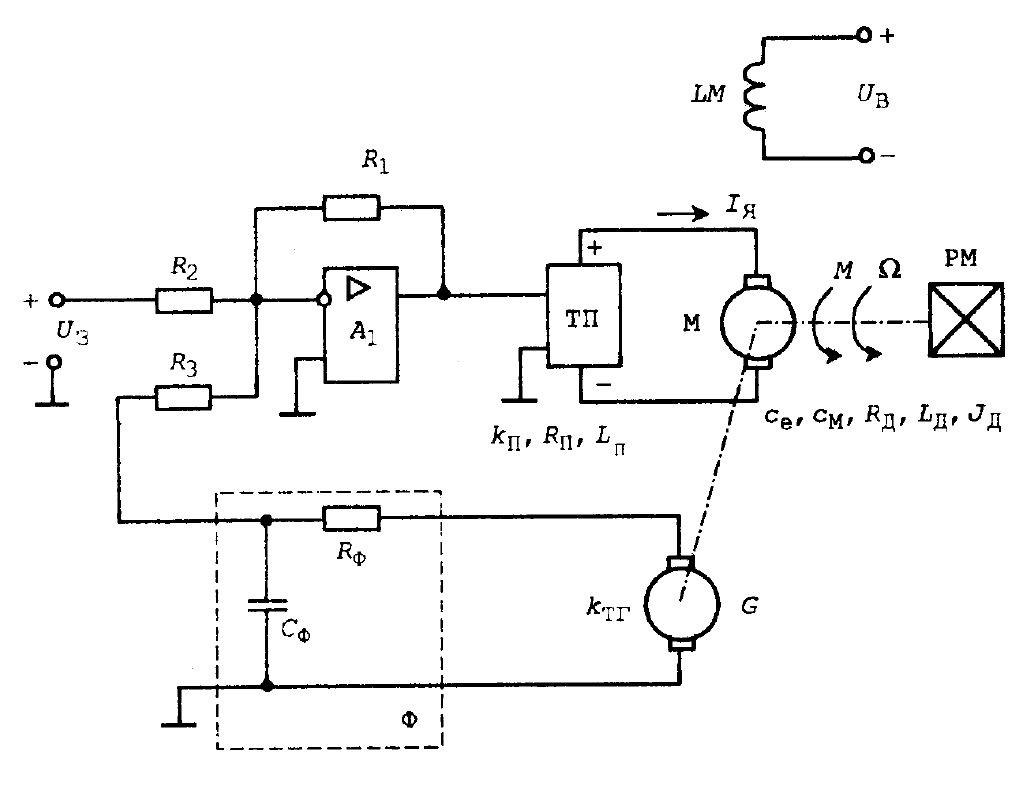

Параметры системы:


$$\begin{array}{l}
L_П =0\ldotp 01\;\mathrm{Henrys}-\mathrm{индуктивность}\;\mathrm{преобразователя}\\
R_П =0\ldotp 9\;\mathrm{Om}-\mathrm{сопротивление}\;\mathrm{преобразователя}\\
L_Д =0\ldotp 01\;\mathrm{Henrys}-\mathrm{индуктивность}\;\mathrm{двигателя}\\
R_Д =4\;\mathrm{Om}-\mathrm{сопротивление}\;\mathrm{двигателя}\\
c_e =1\ldotp 2\;V\cdot s-\mathrm{конструктивная}\;\mathrm{постоянная}\;\mathrm{ДПТ}\;\mathrm{по}\;\mathrm{напряжению}\;\\
c_M =\;1\ldotp 2\;N\cdot \frac{m}{A}-\mathrm{конструктивная}\;\mathrm{постоянная}\;\mathrm{ДПТ}\;\mathrm{по}\;\mathrm{моменту}\\
J_Д =0\ldotp 04\;\mathrm{kg}\cdot m^2 -\mathrm{приведенный}\;\mathrm{момент}\;\mathrm{инерции}\;\\
k_{\mathrm{ТГ}} =0\ldotp 9\;V\cdot s-\mathrm{КУ}\;\mathrm{тахогенератора}\\
k_П =10-\mathrm{КУ}\;\mathrm{силового}\;\mathrm{преобразователя}\\
R_1 =10\;\mathrm{kOm}-\mathrm{сопротивление}\;\mathrm{ОС}\;\mathrm{ОУ}\\
R_2 =R_3 =20\;\mathrm{kOm}-\mathrm{входное}\;\mathrm{сопротивление}\;\mathrm{ОУ}\;и\;\mathrm{сопротивление}\;R_3 \\
R_Ф =20\;\mathrm{kOm}-\mathrm{сопротивление}\;\mathrm{фильтра}\\
C_Ф =5\ldotp 1\;\mathrm{uF}-\mathrm{емкость}\;\mathrm{фильтра}
\end{array}$$


Структурная схема системы в общем виде:

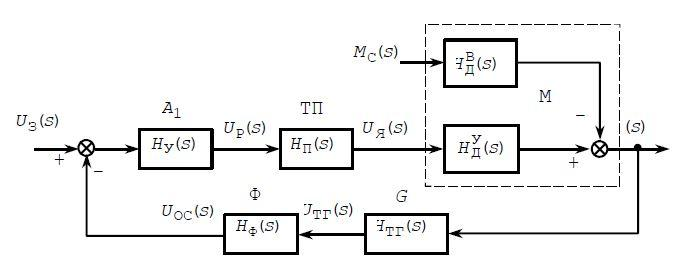

### 2 Передаточные функции и преобразование Лапласа

Запишем список символьных переменных, которыми будем оперировать при дальнейшей работе.

syms K_ampl     % КУ силового преобразователя
syms K_tach     % КУ тахогенератора
syms RF CF TF   % сопротивление, емкость и постоянная времени фильтра
syms R1 R2      % сопротивление ОС и входное, операционного усилителя
syms Rrot Lrot  % сопротивление и индуктивность якоря ДПТ
syms Ce         % конструктивная постоянная ДПТ по напряжению
syms Cm         % конструктивная постоянная ДПТ по моменту
syms b          % коэффициент вязкого трения ДПТ
syms J          % приведенный момент инерции
syms Urot(t)            % напряжение на якоре
syms M(t)               % момент нагрузки на валу ДПТ
syms i(t) omega(t)      % состояния ДПТ

#### 2.1 Составим уравнения для ДПТ

Момент на валу ДПТ пропорционален току якоря и напряженности магнитного поля. Напряженность магнитного поля будем считать постоянной, поэтому момент будет пропорционален току с коэффициентом ***Cm***. 

В ДПТ так же возникает ЭДС самоиндукции, пропорциональная угловой скорости вала с коэффициентом ***Сe***.

На вал ДПТ действует внешний момент ***М*** и сила вязкого трения, пропорциональная скорости вращения с коэффициентом ***b***.

Берем все это во внимание и пользуясь вторым законом Ньютона и вторым законом Кирхгофа записываем следующую систему уравнений:

eqn1 = Urot == Ce*omega + Rrot*i + Lrot*diff(i); % электрическое уравнение ДПТ
eqn2 = J*diff(omega) + b*omega == Cm*i - M; % механическое уравнение ДПТ
eqns = [eqn1; eqn2] % итоговая система уравнений

$$eqns(t) = \left(\begin{array}{c} \mathrm{Urot}\left(t\right)=\mathrm{Lrot}\,\frac{\partial }{\partial t}i\left(t\right)+\mathrm{Ce}\,\omega \left(t\right)+\mathrm{Rrot}\,i\left(t\right)\\ J\,\frac{\partial }{\partial t}\omega \left(t\right)+b\,\omega \left(t\right)=\mathrm{Cm}\,i\left(t\right)-M\left(t\right) \end{array}\right)$$

#### 2.2 Передаточные функции ДПТ по возмущению и по управлению

Чтобы найти решение нашего дифференциального уравнения, т.е. выходной сигнал $y\left(t\right)$, его можно представить в виде действия некоторого оператора на входной сигнал $u\left(t\right)$. Преобразуя по Лапласу дифференциальное уравнение при нулевых начальных условиях приведем левую и правую части к виду:

$W\left(s\right)=\frac{Y\left(s\right)}{U\left(s\right)}$,

где $Y\left(s\right)=L\left\lbrack y\left(t\right)\right\rbrack$, $U\left(s\right)=L\left\lbrack u\left(t\right)\right\rbrack$, а $W\left(s\right)$ - так называемая передаточная функция.

Преобразование Лапласа $L$ временной функции $f\left(t\right)$ (оригинал) в функцию комплексного переменного $F\left(s\right)$ (изображение) определяется с помощью соотношения:


$$L\left\lbrack f\left(t\right)\right\rbrack =\int_0^{\infty } f\left(t\right)\cdot e^{-s\cdot t} \cdot \mathrm{dt}=F\left(s\right)$$


где $s$ - переменная размерностью $c^{-1}$.

Одно полезное для нас свойство этого преобразования такое, что преобразование дифференцирования имеет вид:

$L\left\lbrack \frac{\mathrm{d}}{\mathrm{d}t}f\left(t\right)\right\rbrack =s\cdot F\left(s\right)-f\left(0\right)$.

А так как мы условились, что начальные условия равны нулю, то любое линейное ДУ после преобразования Лапласа превратится в обычный полином.

Преобразуем первое и второе дифференциальное уравнение (ДУ) соответственно:

eqnl1 = laplace(eqn1); % преобразование Лапласа уравнения 1
eqnl2 = laplace(eqn2); % преобразование Лапласа уравнения 2
syms s W I u f
% переменная s, W = L[omega(t)], I = L[i(t)], u - управление, f - возмущение
eqnl1 = subs(eqnl1,[laplace(Urot(t),t,s),laplace(omega(t),t,s),laplace(i(t),t,s),i(0)],[u,W,I,0]) % преобразованное уравнение 1

$$eqnl1 = u=\mathrm{Ce}\,W+\text{I}\,\mathrm{Rrot}+\text{I}\,\mathrm{Lrot}\,s$$

eqnl2 = subs(eqnl2,[laplace(M(t),t,s),laplace(omega(t),t,s),laplace(i(t),t,s),omega(0)],[f,W,I,0]) % преобразованное уравнение 2

$$eqnl2 = W\,b+J\,W\,s=\mathrm{Cm}\,\text{I}-f$$

Исключим ток из уравнений и составим передаточную функцию по управлению, где вход - это напряжение $u$, и по возмущению, где вход - это возмущающий внешний момент $f$.

I = solve(eqnl2,I) % выразим ток из второго уравнения

$$I = \frac{f+W\,b+J\,W\,s}{\mathrm{Cm}}$$

 eqnL = subs(eqnl1) % подставим его в первое уравнение

$$eqnL = u=\mathrm{Ce}\,W+\frac{\mathrm{Rrot}\,\left(f+W\,b+J\,W\,s\right)}{\mathrm{Cm}}+\frac{\mathrm{Lrot}\,s\,\left(f+W\,b+J\,W\,s\right)}{\mathrm{Cm}}$$

Найдем передаточную функцию по управлению:

H_U = simplify(subs(lhs(eqnL)/rhs(eqnL)*W/u,f,0))

$$H\_U = \frac{\mathrm{Cm}}{\mathrm{Rrot}\,b+\mathrm{Ce}\,\mathrm{Cm}+J\,\mathrm{Rrot}\,s+\mathrm{Lrot}\,b\,s+J\,\mathrm{Lrot}\,s^{2}}$$

Найдем передаточную функцию по возмущению:

eqnM = f == solve(eqnL,f);
H_M = simplify(subs(lhs(eqnM)/rhs(eqnM)*W/f,u,0))

$$H\_M = -\frac{\mathrm{Rrot}+\mathrm{Lrot}\,s}{\mathrm{Rrot}\,b+\mathrm{Ce}\,\mathrm{Cm}+J\,\mathrm{Rrot}\,s+\mathrm{Lrot}\,b\,s+J\,\mathrm{Lrot}\,s^{2}}$$

#### 2.3 Передаточные функции всей системы по управлению и по возмущению

Запишем передаточные функции каждого элемента

Передаточная функция силового преобразователя: $H_П \left(s\right)=K_{\mathrm{ampl}}$.

Передаточная функция тахогенератора: $H_{\mathrm{ТГ}} \left(s\right)=K_{\mathrm{tach}}$.

Передаточная функция фильтра: $H_Ф \left(s\right)=\frac{1}{\mathrm{CF}\,\mathrm{RF}\,p+1}$.

Передаточная функция операционного усилителя: $H_У \left(s\right)=\frac{\mathrm{R1}}{\mathrm{R2}}$.

H_FA = K_ampl; % передаточная функция силового преобразователя
H_G = K_tach; % передаточная функция тахогенератора
H_F = 1/(RF*CF*s+1); % передаточная функция фильтра
H_OA = R1/R2; % передаточная функция операционного усилителя

Составим передаточную функцию замкнутой системы по управлению:

W1 = H_OA*H_FA*H_U;
W2 = H_G*H_F;
W_sys_u = simplify(expand(W1/(1+W1*W2))) % передаточная функция по управлению всей системы

$$W\_sys\_u = \frac{\mathrm{Cm}\,K_{\mathrm{ampl}}\,R_{1}\,\left(\mathrm{CF}\,\mathrm{RF}\,s+1\right)}{\mathrm{Ce}\,\mathrm{Cm}\,R_{2}+R_{2}\,\mathrm{Rrot}\,b+J\,\mathrm{Lrot}\,R_{2}\,s^{2}+\mathrm{Cm}\,K_{\mathrm{ampl}}\,K_{\mathrm{tach}}\,R_{1}+J\,R_{2}\,\mathrm{Rrot}\,s+\mathrm{Lrot}\,R_{2}\,b\,s+\mathrm{CF}\,\mathrm{Ce}\,\mathrm{Cm}\,R_{2}\,\mathrm{RF}\,s+\mathrm{CF}\,R_{2}\,\mathrm{RF}\,\mathrm{Rrot}\,b\,s+\mathrm{CF}\,J\,\mathrm{Lrot}\,R_{2}\,\mathrm{RF}\,s^{3}+\mathrm{CF}\,J\,R_{2}\,\mathrm{RF}\,\mathrm{Rrot}\,s^{2}+\mathrm{CF}\,\mathrm{Lrot}\,R_{2}\,\mathrm{RF}\,b\,s^{2}}$$

Составим передаточную функцию замкнутой системы по возмущению:

W3 = W1*-W2;
W4 = 1/(1-W3);
W_sys_M = simplify(expand(H_M*W4)) % передаточная функция по возмущению всей системы

$$W\_sys\_M = -\frac{R_{2}\,\left(\mathrm{CF}\,\mathrm{RF}\,s+1\right)\,\left(\mathrm{Rrot}+\mathrm{Lrot}\,s\right)}{\mathrm{Ce}\,\mathrm{Cm}\,R_{2}+R_{2}\,\mathrm{Rrot}\,b+J\,\mathrm{Lrot}\,R_{2}\,s^{2}+\mathrm{Cm}\,K_{\mathrm{ampl}}\,K_{\mathrm{tach}}\,R_{1}+J\,R_{2}\,\mathrm{Rrot}\,s+\mathrm{Lrot}\,R_{2}\,b\,s+\mathrm{CF}\,\mathrm{Ce}\,\mathrm{Cm}\,R_{2}\,\mathrm{RF}\,s+\mathrm{CF}\,R_{2}\,\mathrm{RF}\,\mathrm{Rrot}\,b\,s+\mathrm{CF}\,J\,\mathrm{Lrot}\,R_{2}\,\mathrm{RF}\,s^{3}+\mathrm{CF}\,J\,R_{2}\,\mathrm{RF}\,\mathrm{Rrot}\,s^{2}+\mathrm{CF}\,\mathrm{Lrot}\,R_{2}\,\mathrm{RF}\,b\,s^{2}}$$

#### 2.4 Решение полученной системы с помощью обратного преобразования Лапласа:

Обратное преобразование Лапласа $L^{-1}$ функции $F\left(s\right)$ во временную функцию $f\left(t\right)$ осуществляется по формуле:


$$f\left(t\right)=L^{-1} \left\lbrack F\left(s\right)\right\rbrack =\frac{1}{2\pi j}\int_{\sigma -j\cdot \infty }^{\sigma +j\cdot \infty } F\left(s\right)\cdot e^{s\cdot t} \cdot \mathrm{ds}$$


где $j=\sqrt{-1}$, а постоянная $\sigma$ выбирается так, чтобы интеграл сходился.

Обратное преобразование Лапласа позволяет удобно находить решение ДУ при стандартных входных воздействиях, для которых известны оригиналы и изображения.

Найдем решение нашей системы при управлении ступенчатым сигналом.

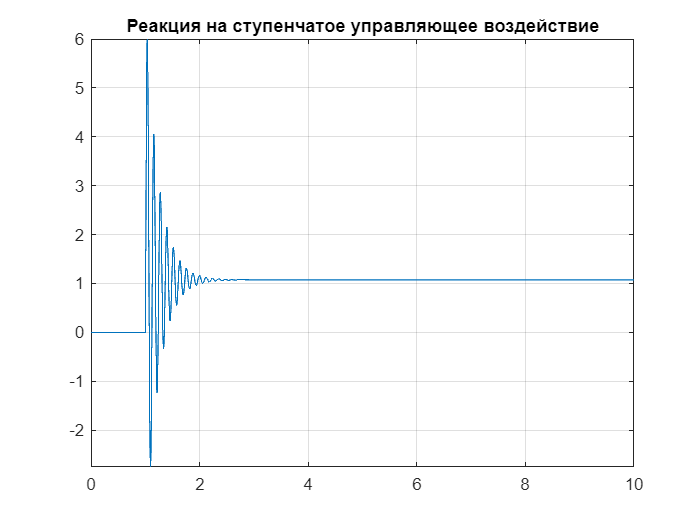

param % загрузка численных параметров системы
syms t % время
g0 = heaviside(t-1); % входной сигнал
G0 = laplace(g0,s); % изображение для входного сигнала
Yp = subs(G0*W_sys_u); % изображение выходного сигнала
ytu = ilaplace(Yp); % оригинал выходного сигнала
fplot(ytu,[0 10])
title('Реакция на ступенчатое управляющее воздействие')
grid on

Найдем реакцию системы на постоянное возмущающее единичное воздействие.

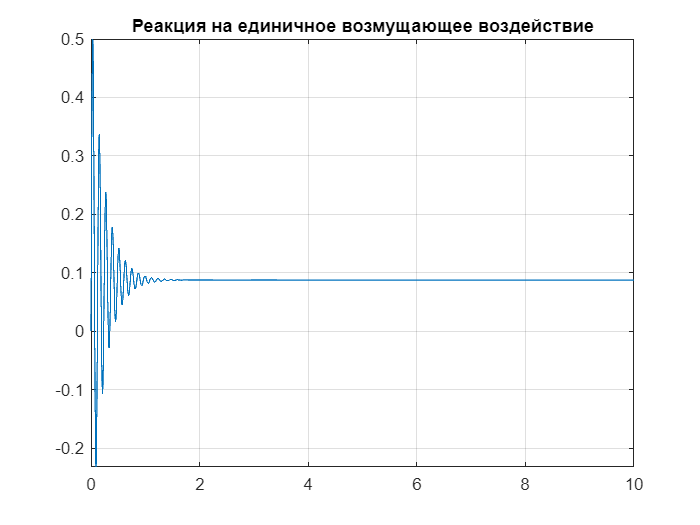

g0 = 1; % входной сигнал
G0 = laplace(g0,s); % изображение входного сигнала
Yp = subs(G0*-W_sys_M); % изображение выходного сигнала
ytM = ilaplace(Yp); % оригинал выходного сигнала
fplot(ytM,[0 10])
title('Реакция на единичное возмущающее воздействие')
grid on

Найдем решение системы при совместном воздействии как по управлению, так и по возмущению.

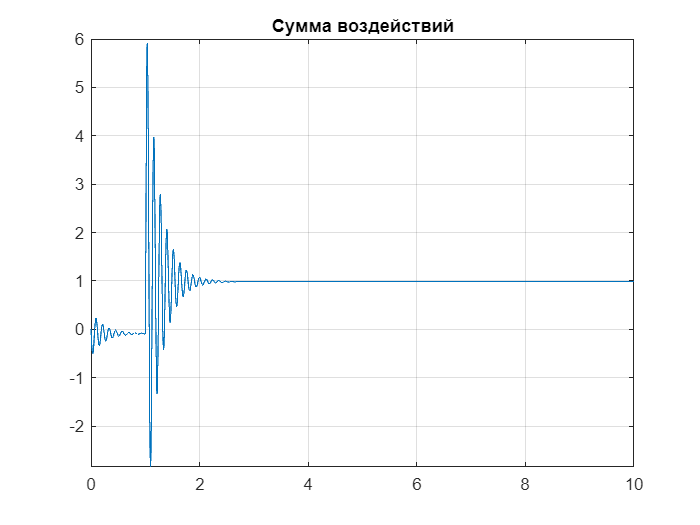

yt = ytu-ytM; % сумма выходных сигналов
fplot(yt,[0 10])
title('Сумма воздействий')
grid on

#### 2.5 Сборка системы как объекта Control System Toolbox

Для удобной работы с линейными системами в пакете Matlab предусмотрено приложение Control System Toolbox.

Соберем нашу систему в терминах этого приложения.

[V,S] = odeToVectorField(eqns) % уравнения ДПТ в пространстве состояний

$$V = \left(\begin{array}{c} -\frac{M\left(t\right)-\mathrm{Cm}\,Y_{2}+b\,Y_{1}}{J}\\ -\frac{\mathrm{Ce}\,Y_{1}-\mathrm{Urot}\left(t\right)+\mathrm{Rrot}\,Y_{2}}{\mathrm{Lrot}} \end{array}\right)$$

$$S = \left(\begin{array}{c} \omega \\ i \end{array}\right)$$

Vc = feval(symengine,'evalAt',V,'Y = [y1,y2]'); % техническое переименование переменных
syms y1 y2 % символьные переменные
y = [y1;y2];
A = jacobian(Vc,y) % найдем матрицу А модели ДПТ

$$A = \left(\begin{array}{cc} -\frac{b}{J} & \frac{\mathrm{Cm}}{J}\\ -\frac{\mathrm{Ce}}{\mathrm{Lrot}} & -\frac{\mathrm{Rrot}}{\mathrm{Lrot}} \end{array}\right)$$

A = double(subs(A)); % подставим численные значения в A
B = jacobian(Vc,[Urot;M]) % найдем матрицу B ДПТ

$$B(t) = \left(\begin{array}{cc} 0 & -\frac{1}{J}\\ \frac{1}{\mathrm{Lrot}} & 0 \end{array}\right)$$

B = double(subs(B)); % подставим численные значения в B
C = [1 0]; % матрица C ДПТ
D = 0; % матрица D ДПТ
DC_Motor = ss(A,B,C,D,'StateName',{'omega','i'},'InputName',{'U','M'},'OutputName',{'omega'}); % модель ДПТ
DC_Motor = zpk(DC_Motor); % передаточная функция ДПТ
DC_Motor.DisplayFormat = 'time constraint' % формат отображения модели ДПТ

DC_Motor =
 
  From input "U" to output "omega":
           0.62176
  --------------------------
  (1+0.09838s) (1+0.004213s)
 
  From input "M" to output "omega":
    -2.5389 (1+0.004082s)
  --------------------------
  (1+0.09838s) (1+0.004213s)
 
Continuous-time zero/pole/gain model.



Силовой преобразователь $H_П \left(s\right)$:

H_FA = tf(K_ampl); % передаточная функция силового преобразователя
H_FA.InputName = 'b'; % вход преобразователя
H_FA.OutputName = 'U'; % выход преобразователя

Тахогенератор $H_{\mathrm{ТГ}} \left(s\right)$:

H_G = tf(K_tach); % передаточная функция тахогенератора
H_G.InputName = 'omega'; % вход тахогенератора
H_G.OutputName = 'f'; % выход тахогенератора

Фильтр $H_Ф \left(s\right)$:

H_F = tf(1,[TF 1]); % передаточная функция фильтра
H_F.InputName = 'f'; % вход фильтра
H_F.OutputName = 'e'; % выход фильтра

Операционный усилитель $H_У \left(s\right)$:

H_OA = tf(R1/R2); % передаточная функция ОУ
H_OA.InputName = 'a'; % вход ОУ
H_OA.OutputName = 'b'; % выход ОУ

Соберем замкнутую систему:

sum = sumblk('a = u - e'); % сумматор
Plant = zpk(connect(DC_Motor,H_FA,H_G,H_F,H_OA,sum,{'u','M'},'omega')); % передаточная функция системы
Plant.DisplayFormat = 'time constraint'; % формат отображения

Определим передаточную функцию системы по управляющему воздействию:

Plant(1)

ans =
 
  From input "u" to output "omega":
                   1.0728 (1+0.102s)
  ---------------------------------------------------
  (1+0.004017s) (1 + 0.1597(0.01906s) + (0.01906s)^2)
 
Continuous-time zero/pole/gain model.



Определим передаточную функцию системы по возмущающему воздействию:

Plant(2)

ans =
 
  From input "M" to output "omega":
           -0.08761 (1+0.004082s) (1+0.102s)
  ---------------------------------------------------
  (1+0.004017s) (1 + 0.1597(0.01906s) + (0.01906s)^2)
 
Continuous-time zero/pole/gain model.



### 3 ЛАФЧХ и запасы устойчивости

Заметим, что при действии на вход линейной системы гармоническим сигналом, выход системы будет то же гармоническим сигналом той же частоты, но другой амплитуды $A$ и сдвинут по фазе $\phi$. Поэтому для анализа таких систем удобно использовать логарифмическую амплитудно-фазовую частотную характеристику (ЛАФЧХ), которая демонстрирует отклик системы на гармонические сигналы разной частоты в логарифмическом масштабе.

Совершая замену переменной в передаточной функции $s\to j\cdot w$ (где $w$ - частота), зависимость амплитуды и фазы выходного сигнала от частоты входного определяется по формулам:

$\left|W\left(j\cdot w\right)\right|=A\left(w\right)$ и $\angle W\left(j\cdot w\right)=\phi \left(w\right)$.

Мы можем оценить качество замкнутой системы по частотным характеристикам разомкнутой системы.

Важными оценками качества системы являются запасы устойчивости по амплитуде и по фазе. Они показывают, насколько могут измениться параметры системы в сравнении с расчетными, чтобы система сохранила устойчивость.

Запас устойчивости по амплитуде показывает дополнительное усиление контура, которое необходимо, чтобы вывести систему на границу устойчивости.

Запас устойчивости по фазе показывает какой дополнительный сдвиг фазы необходим для того, чтобы вывести систему на границу устойчивости.

#### Определим запасы устойчивости нашей разомкнутой системы

Составим передаточную функцию разомкнутой системы по управлению.

Wopen = zpk(connect(H_OA,H_FA,DC_Motor(1),H_G,H_F,'a','e'));
Wopen.DisplayFormat = 'time constraint'

Wopen =
 
  From input "a" to output "e":
                 27.979
  -------------------------------------
  (1+0.102s) (1+0.09838s) (1+0.004213s)
 
Continuous-time zero/pole/gain model.



Оценим запасы устойчивости по ЛАФЧХ.

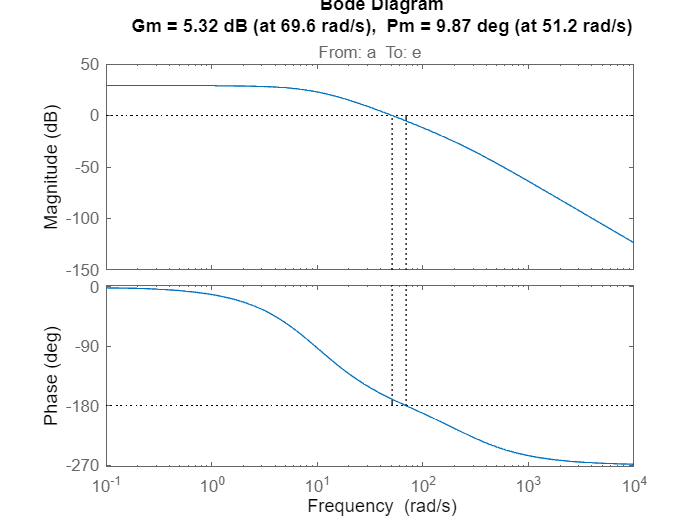

margin(Wopen)

Как видно из графика, запас устойчивости по амплитуде ***Gm = 5.32 дБ ***при частоте 69 рад/с и запас устойчивости по фазе ***Pm = 9.87 градусов*** при частоте 51 рад/с.

На ровне с ЛАФЧХ, для оценки запасов устойчивости используется диаграмма Найквиста. Это кривая на комплексной плоскости, соответствующая зависимости реальной и мнимой части передаточной функции от частоты. Критерий Найквиста наглядно показывает устойчивость замкнутой системы. Если годограф разомкнутой системы не охватывает точку $\left(-1;\;0\right)$, то система устойчива.

Построим годограф Найквиста разомкнутой системы:

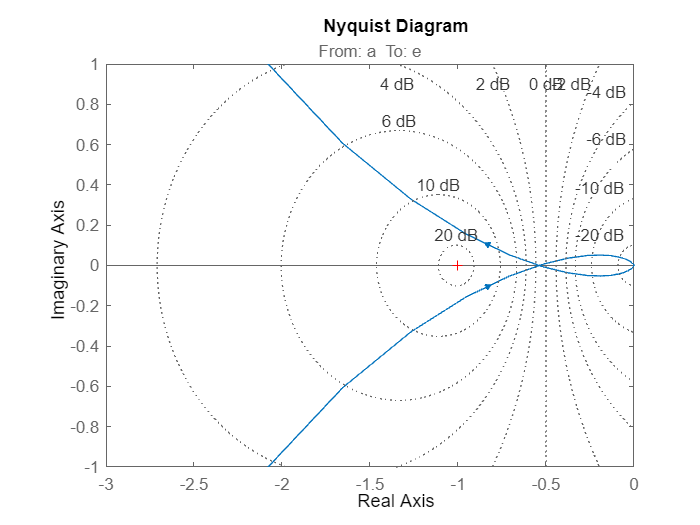

nyquist(Wopen)
grid on
xlim([-3 0])
ylim([-1 1])

Из графика видно, что годограф не охватывает точку  $\left(-1;\;0\right)$, а значит замкнутая система устойчива.

Запасы устойчивости найдены выше независимо друг от друга. Но в реальных системах часто бывает необходимо знать какой существует запас по одновременному усилению и запаздыванию.

Для решения этой задачи существует понятие диска маржинальности. Это окружность на диаграмме Найквиста, которая демонстрирует запас на который еще можно сдвинуть годограф.

Найдем допустимые одновременные запасы по фазе и усилению:

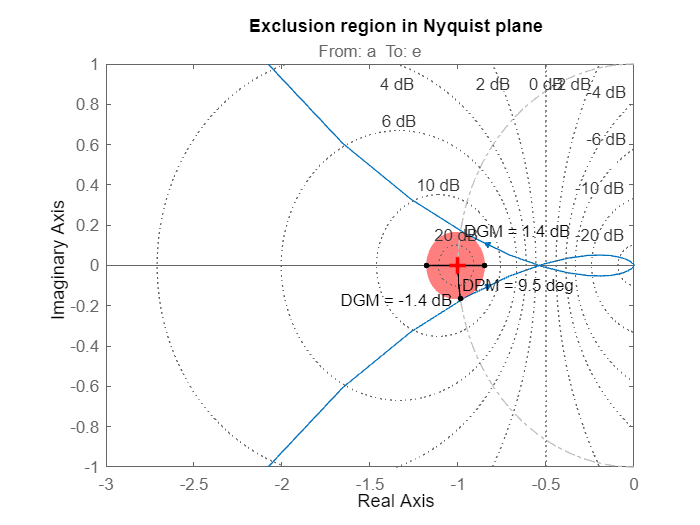

DM = diskmargin(Wopen); % запасы одновременной устойчивости
figure
h = nyquistplot(Wopen); % диаграмма Найквиста
grid on, hold on
zoomcp(h)
diskmarginplot(DM.GainMargin,'nyquist')
hold off
xlim([-3 0])
ylim([-1 1])

По графику видно, что одновременный запас по усилению и по фазе для "худшего" случая равен ***1.4 дБ и 9.5 градуса***.

### 4 Расчет корректирующего звена методом желаемой ЛАЧХ

Синтез САУ методом желаемой ЛАЧХ часто используется в различных студенческих работах. Этот метод разработанный В.В. Солодовниковым, основывается на соответствии между логарифмическими частотными характеристиками разомкнутой системы и ее статическими и динамическими свойствами в замкнутом состоянии. Метод используется для систем минимально-фазового типа [Теория автоматического управления под реакцией Воронова А.А. Часть 1, стр. 271, 1986г].

Зададимся следующими требованиями к замкнутой САУ:

- ошибка в установившемся режиме $\delta =10%$;

- время переходного процесса $t_p =0\ldotp 8\;с$;

- перерегулирование $\sigma =20%$.

delta = 10; % ошибка
tp = 0.8; % время переходного процесса
sigma = 20; % перерегулирование

Построим асимптотическую ЛАЧХ некорректированной разомкнутой САУ.

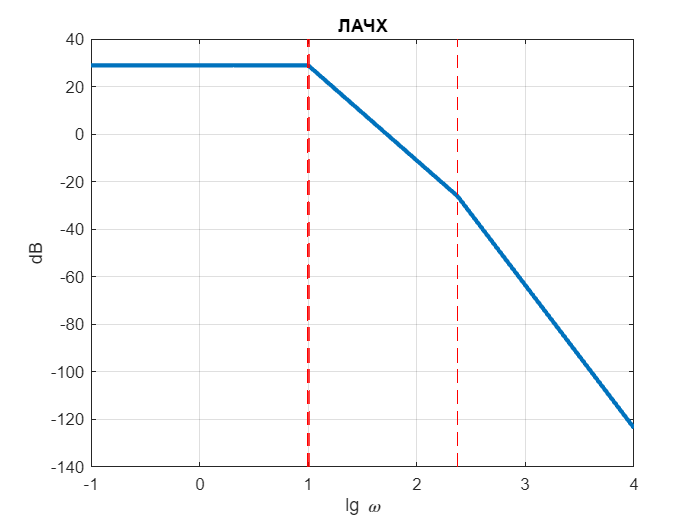

figure
wlim = [-1 4]; % диапазон интересующих частот
plotL(Wopen,wlim)
hold on

#### 4.1 Желаемая ЛАЧХ

Построим желаемую ЛАЧХ разомкнутой системы, имеющую желаемые статические и динамические свойства.

Желаемая ЛАЧХ состоит из трех основных асимптот: низкочастотной, среднечастотной и высокочастотной.

Низкочастотная часть желаемой ЛАЧХ определяет статические свойства. Проведем эту прямую под наклоном ***-20 дБ/дек ***в низкочастотной области ЛАЧХ.

Среднечастотная часть определяет устойчивость и запас устойчивости системы. Проведем асимптоту так же с наклоном ***-20 дБ/дек*** пересекая ось абсцисс на частоте среза. Концы отрезка - это место пересечения с прямыми запаса по усилению $\Delta L$.

По номограммам Солодовникова находим частоту среза и запас по усилению.

[omegacut,Lm,~] = nomosol(sigma,tp) % частота среза и запас по усилению соответственно

omegacut = 9.4248

Lm = 28.3741

Высокочастотная часть строится из принципа минимальной сложности реализации. Для этого проведем асимптоту параллельно ЛАЧХ ОУ, т.е. под наклоном в ***-60 дБ/дек***.

В результате получим следующую ЛАЧХ:

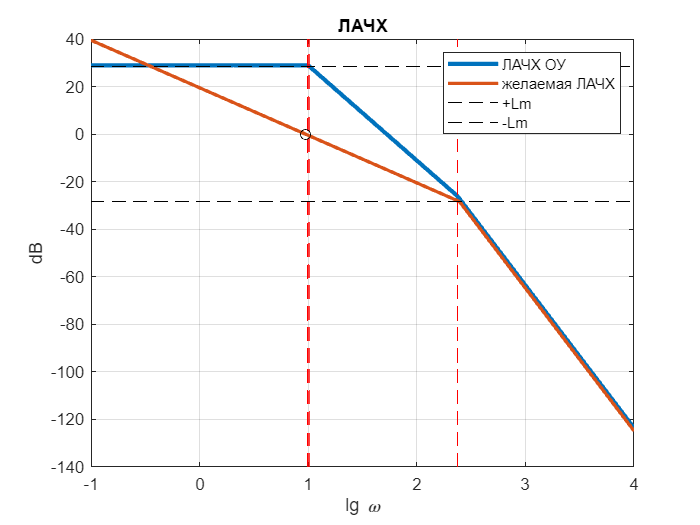

[L0,~,lgw1,~] = freqasymp(Wopen,wlim,1); % ЛАЧХ ОУ
laf = Line2d;
laf = LinePointLengthAngle(laf,[0 log10(omegacut)],1,-20,'db/dec'); % прямая с наклоном -20дБ/дек
wlf = evalY(laf,Lm);
whf = evalY(laf,-Lm);
llf = Line2d;
laf = LinePointLengthAngle(laf,[Lm wlf],1,-20,'db/dec'); % прямая с наклоном -20дБ/дек
Llf = evalX(laf,wlim(1)); % ордината пересечения линий
lhf = Line2d;
lhf =  LinePointLengthAngle(lhf,[-Lm whf],1,-60,'db/dec'); % прямая с наклоном -60дБ/дек
Lhf = evalX(lhf,wlim(2)); % ордината пересечения линий
Ldes = [Llf; Lm; -Lm; Lhf]; % желаемая амплитуда ЛАЧХ
lgwdes = [wlim(1); wlf; whf; wlim(2)]; % желаемые соответствующие частоты
plot(lgwdes,Ldes,'LineWidth',2)
line(wlim,[Lm Lm],...
'Color', 'k', 'LineStyle', '--') % верхний запас устойчивости
line(wlim,[-Lm -Lm],...
'Color', 'k', 'LineStyle', '--') % нижний запас устойчивости
plot(log10(omegacut),0,'o','Color','k')
legend('ЛАЧХ ОУ','','','','желаемая ЛАЧХ','+Lm','-Lm')

#### 4.2 ЛАЧХ корректирующего устройства (регулятора)

Построим ЛАЧХ последовательного корректирующего устройства путем графического вычитания из желаемой ЛАЧХ ЛАЧХ ОУ.

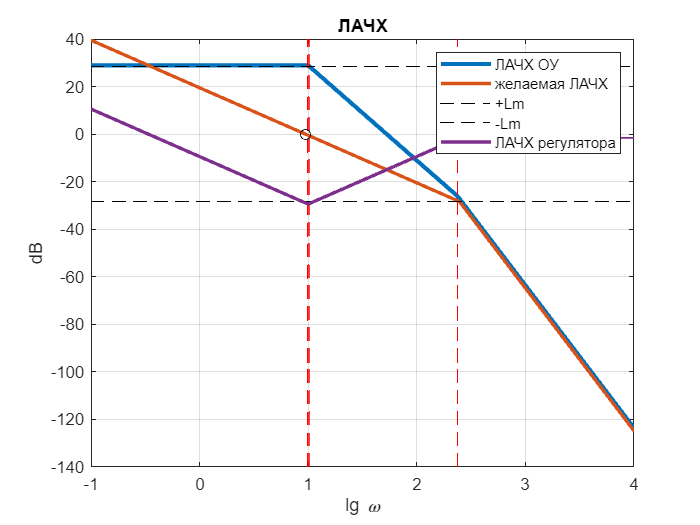

lgw = sort(vertcat(lgwdes,lgw1)); % частоты желаемой ЛАЧХ и ЛАЧХ ОУ
Ldes = interp1(lgwdes,Ldes,lgw); % амплитуды желаемой ЛАЧХ
L0 = interp1(lgw1,L0,lgw); % амплитуды ЛАЧХ ОУ
Lreg = Ldes-L0; % вычитаем из желаемой ЛАЧХ ЛАЧХ ОУ
plot(lgw,Lreg,'LineWidth',2)
hold off
legend('ЛАЧХ ОУ','','','','желаемая ЛАЧХ','+Lm','-Lm','','ЛАЧХ регулятора')

#### 4.3 Определение передаточной функции корректирующего звена

Рассчитаем желаемый КУ разомкнутой системы.

K0 = 1/(delta/100); % желаемый КУ

Определим по виду ЛАЧХ передаточную функцию корректирующего звена. Изменение на -20 дБ/дек соответствует домножению передаточной функции на апереодическое звено, а изменение на +20 дБ/дек соответствует домножению на обратное апериодическое. Коэффициент усиления находим в зависимости от требуемой точности.

w1 = 10; % частота первого динамического звена
w2 = 10^2.4; % частота второго динамического звена
T1 = 1/w1; % постоянная времени 1 звена
T2 = 1/w2; % постоянная времени 2 звена
s = tf('s');
KP = K_ampl*K_tach*R1/R2*0.62176; % КУ разомкнутой системы
Kdes = K0/KP; % КУ компенсатора
Compensator = Kdes/s*(T1*s+1)^2/(T2*s+1); % передаточная функция компенсатора
Compensator.InputName = 'cI';
Compensator.OutputName = 'cO';
Compensator = zpk(Compensator);
Compensator.DisplayFormat = 'time constraint'

Compensator =
 
  From input "cI" to output "cO":
  0.35741 (1+0.1s)^2
  ------------------
   s (1+0.003981s)
 
Continuous-time zero/pole/gain model.



#### 4.4 Проверка 

Построим переходную функцию замкнутой САУ с компенсатором.

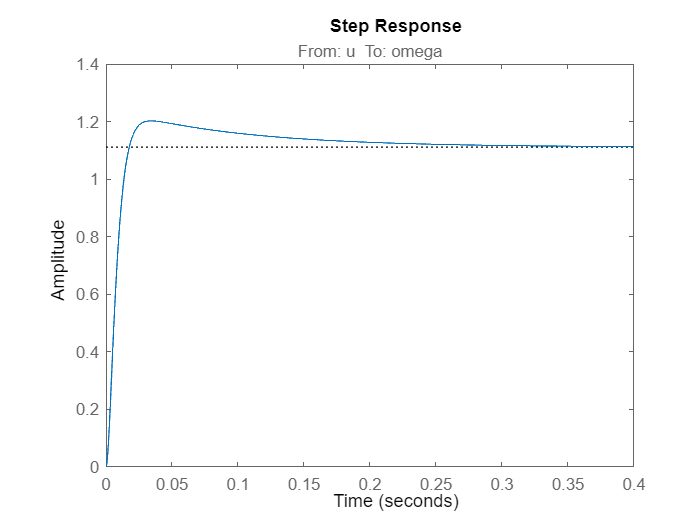

H_OA2 = H_OA;
H_OA2.InputName = 'cO';
sum2 = sumblk('cI = u - e');
Sys1 = tf(connect(DC_Motor,Compensator,H_FA,H_G,H_F,H_OA2,sum2,{'u','M'},'omega')); % замкнутая САУ
step(Sys1(1))

По рисунку определим основные показатели качества регулирования. Ошибка в установившемся режиме $\delta =11%$, что немного больше требуемого значения, но ее можно уменьшить, регулируя дополнительный усилитель на входе. Время переходного процесса $t_p =0\ldotp 174\;с$. Перерегулирование $\sigma =8%$.

Запасы по усилению и по фазе найдем ниже:

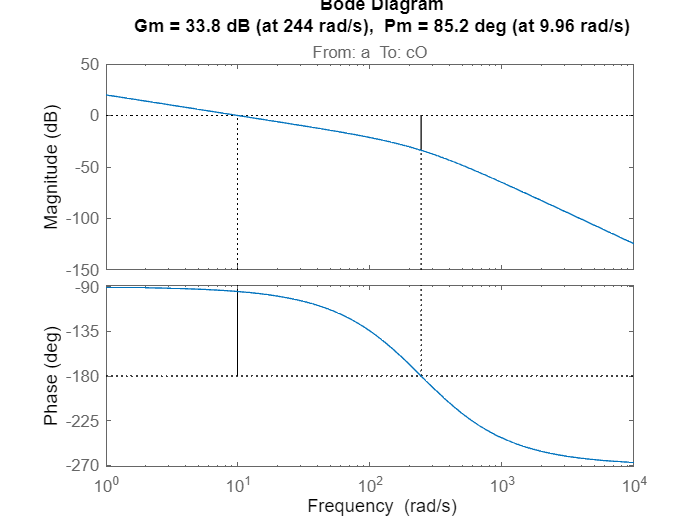

margin(Compensator*Wopen)

### 5 Автоматический расчет компенсатора в Control System Designer

Control System Toolbox в пакете Matlab предоставляет нам удобное приложение с интуитивно понятным интерфейсом и множеством полезных инструментов для разработки регуляторов - Control System Designer.

Для начала работы в нем надо подготовить передаточные функции для разомкнутой системы без ОС и передаточную функцию ОС.

G = connect(H_OA,H_FA,DC_Motor(1),'a','omega'); % передаточная функция петли
H = connect(H_G,H_F,'omega','e'); % передаточная функция обратной связи

Запускаем Control System Designer из панели APPS и в окне Edit Architecture выбираем подготовленные передаточные функции.

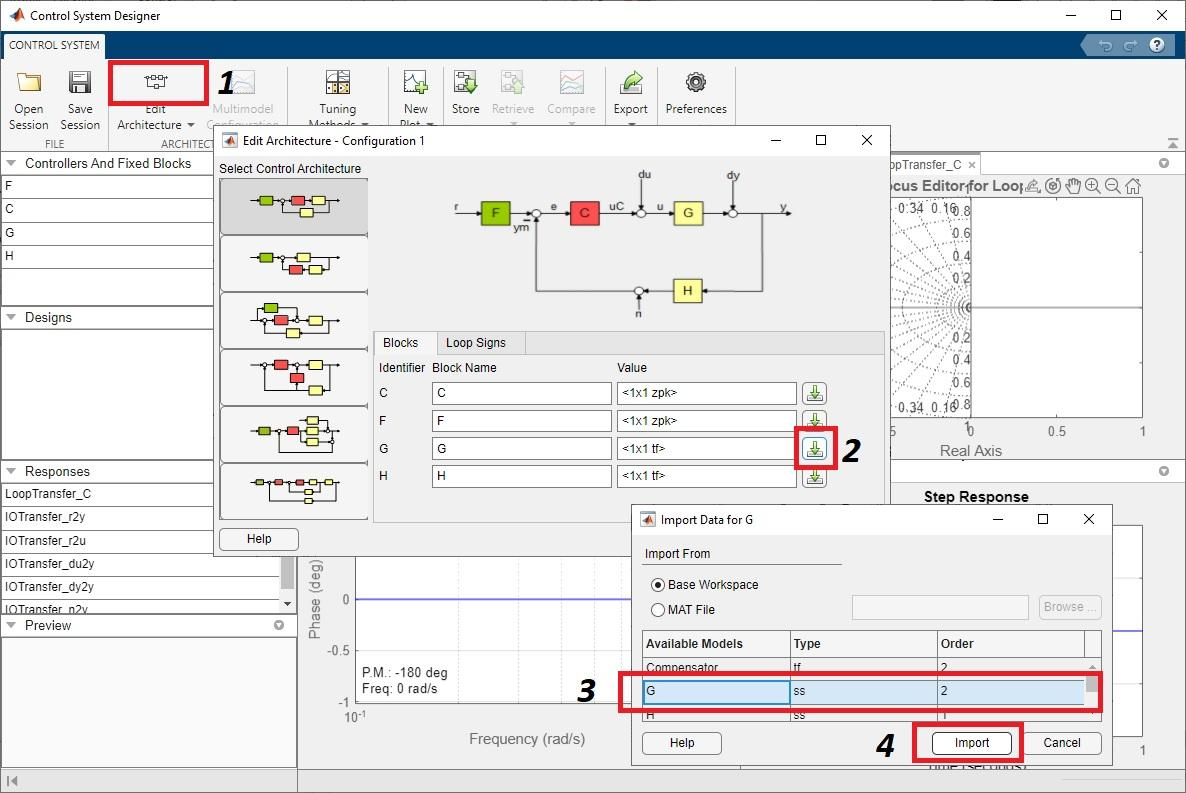

Далее выбираем метод расчета компенсатора по заданной желаемой форме разомкнутой системы. Этот метод рассчитывает контроллер так, чтобы итоговая ЛАЧХ была максимально близка к заданной. Задать ЛАЧХ можно с помощью ширины полосы частот $\omega_b$, тогда ЛАЧХ будет стремится к ЛАЧХ интегратора $\frac{\omega_b }{s}$ или ЛАЧХ заданной пользователем передаточной функции.

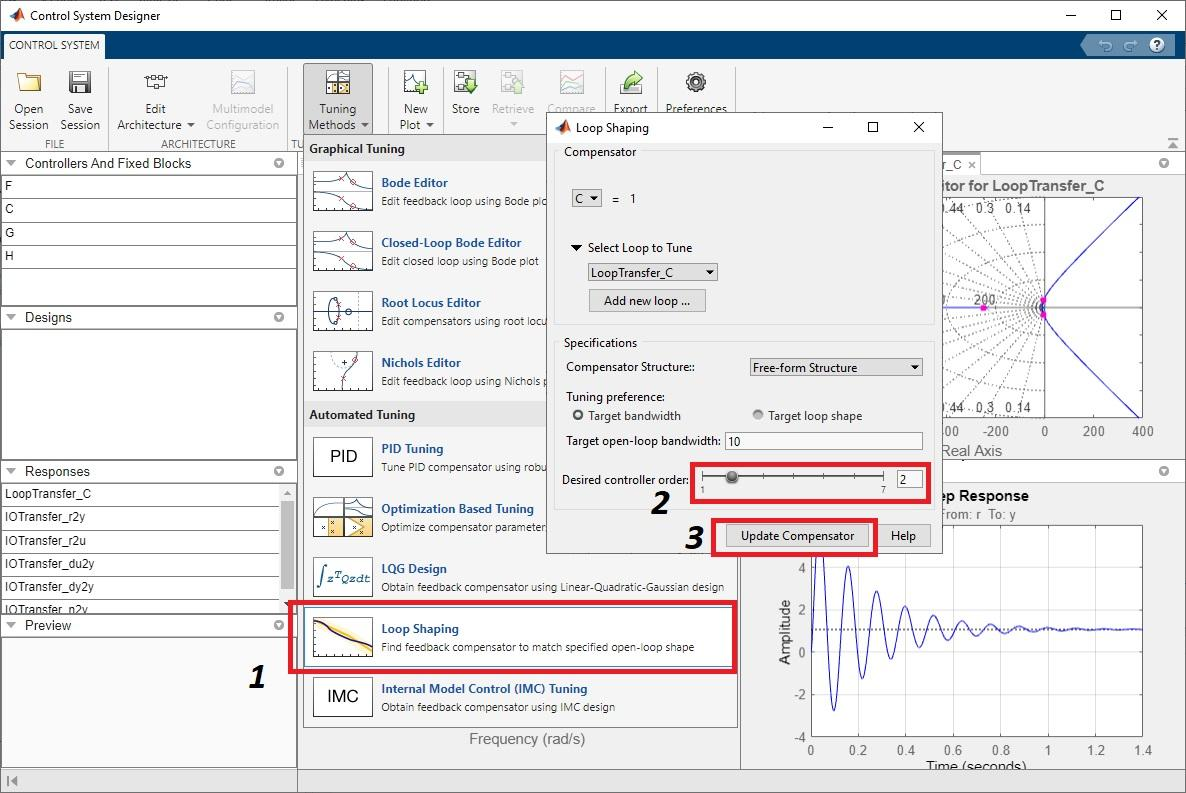

Сравним качество регулирования рассчитаного автоматически компенсатора с первым компенсатором, который мы построили методом желаемой ЛАЧХ.

load('Comensators.mat') % загрузим LTI модель компенсатора, подготовленного в Control System Designer
CompensatorCD.InputName = 'cI';
CompensatorCD.OutputName = 'cO';
CompensatorCD.DisplayFormat = 'time constraint'

CompensatorCD =
 
  From input "cI" to output "cO":
  0.32107 (1 + 1.934(0.1071s) + (0.1071s)^2)
  ------------------------------------------
                s (1+0.0175s)
 
Name: C
Continuous-time zero/pole/gain model.



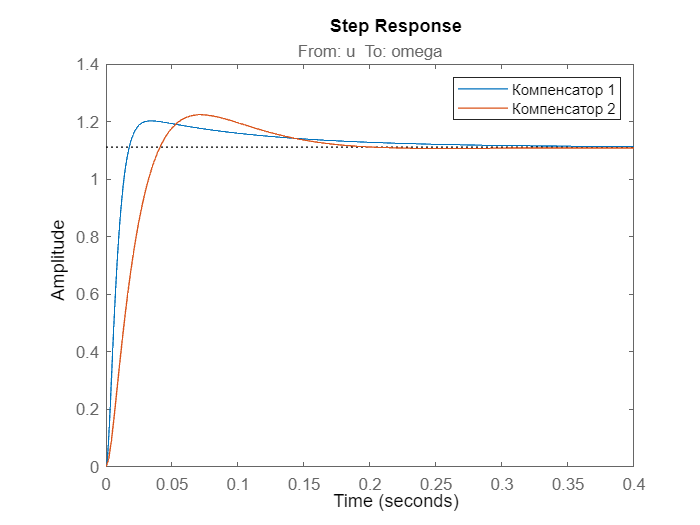

Sys2 = tf(connect(DC_Motor,CompensatorCD,H_FA,H_G,H_F,H_OA2,sum2,{'u','M'},'omega')); % замкнутая САУ
step(Sys1(1),Sys2(1))
legend('Компенсатор 1','Компенсатор 2')

По рисунку определим основные показатели качества регулирования. Ошибка в установившемся режиме так же $\delta =11%$, время переходного процесса $t_p =0\ldotp 153\;с$, перерегулирование $\sigma =10%$.

Найдем запасы по усилению и по фазе:

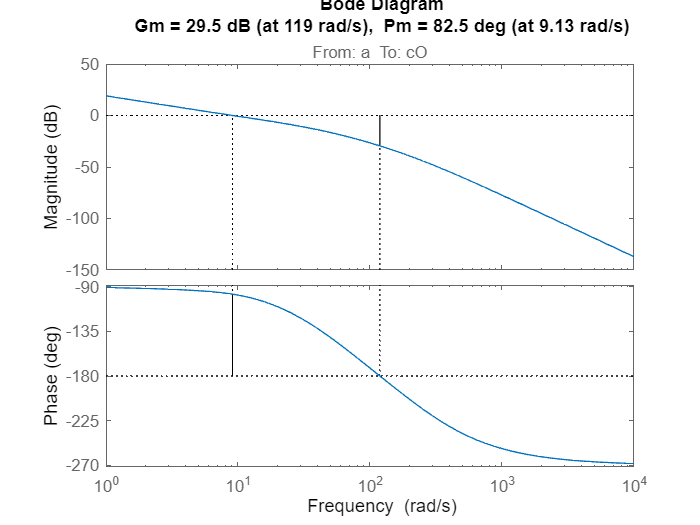

margin(CompensatorCD*Wopen)

### 6 Автоматический расчет ПИД регулятора в Matlab

Управление нашей электромеханической системой можно осуществлять так же с помощью ПИД регулятора.

Control System Toolbox обладает большим набором инструментов по расчету ПИД регуляторов. Один из способов - это расчет командой pidtune.

pidComp0 = pid(1,1,1); % создадим модель ПИД контроллера
opts = pidtuneOptions('PhaseMargin',74,'DesignFocus','reference-tracking'); % зададим параметры для расчета
[PIDComp,~] = pidtune(Wopen,pidComp0,6,opts) % расчитаем ПИД регулятор для частоты среза 6 рад/с

PIDComp =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 0.0359, Ki = 0.245, Kd = 0.00131
 
Continuous-time PID controller in parallel form.



PIDComp.InputName = 'cI';
PIDComp.OutputName = 'cO';

Сравним переходные функции:

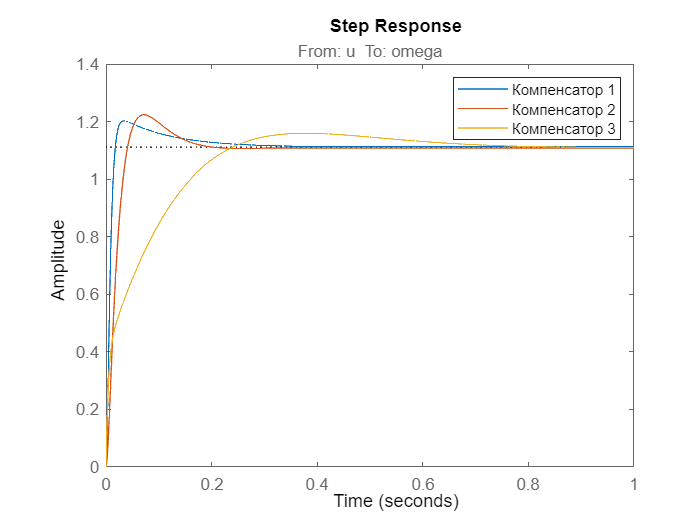

Sys3 = tf(connect(DC_Motor,PIDComp,H_FA,H_G,H_F,H_OA2,sum2,{'u','M'},'omega'));
step(Sys1(1),Sys2(1),Sys3(1))
legend('Компенсатор 1','Компенсатор 2','Компенсатор 3')

Ошибка $\delta =11%$, время переходного процесса $t_p =0\ldotp 58\;с$, перерегулирование $\sigma =4%$.

Запасы по усилению и по фазе:

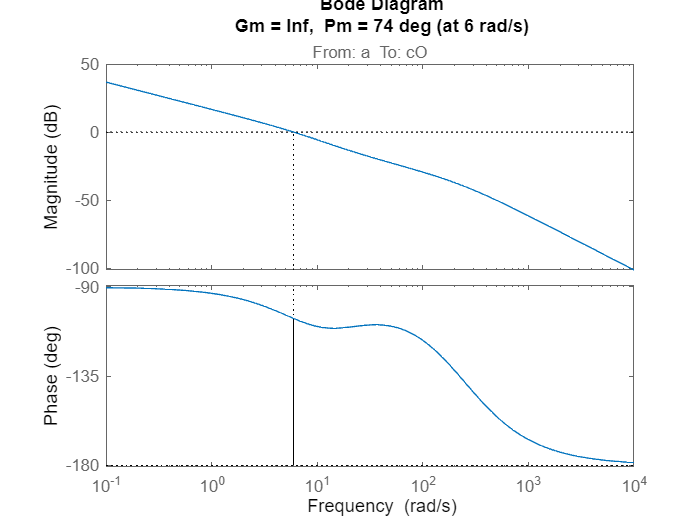

margin(PIDComp*Wopen)

### 7 Автоматический расчет компенсатора в Control System Tuner

Еще один удобный способ найти удовлетворяющий параметрам компенсатор - это использование команды systune. Для этого требуется подготовить genss модель, в которой будет находиться искомый компенсатор.

CompensatorCT = tunableTF('C1',2,2); % искомый компенсатор с 2 нулями и 2 полюсами
CompensatorCT.InputName = 'cI';
CompensatorCT.OutputName = 'cO';
Sys4 = connect(DC_Motor,CompensatorCT,H_FA,H_G,H_F,H_OA2,sum2,{'u','M'},'omega'); % genss модель

Далее зададим целевую переходную функцию по управлению и реакцию системы на возмущение.

Strack = TuningGoal.StepTracking('u','omega',0.1,10); % зададим требуемую переходную функцию
Srej = TuningGoal.StepRejection('M','omega',1,1); % зададим ограничения по возмущению

Проведем расчет.

options = systuneOptions('Display','off','MinDecay',1e-9); % выбор опций
[SysTune,~,~] = systune(Sys4,Strack,Srej,options); % поиск удовлетворяющего требованиям компенсатора

Результат расчета.

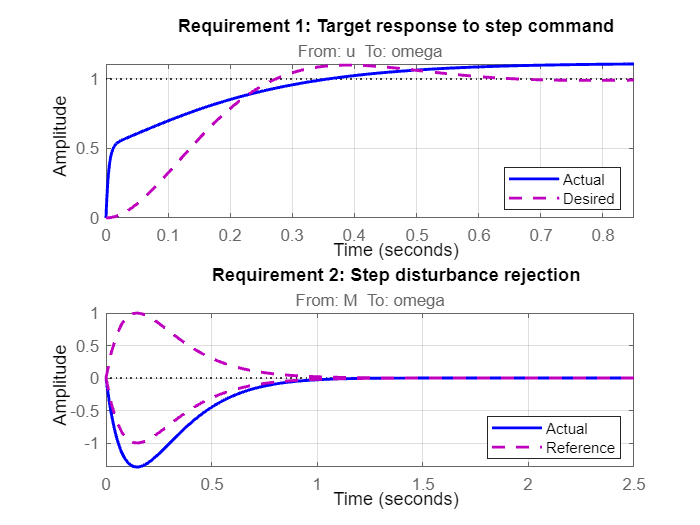

viewGoal([Strack,Srej],SysTune)

По рисунку определим, что ошибка в установившемся режиме $\delta =11\;%$, время переходного процесса $t_p =0\ldotp 5\;с$, перерегулирование $\sigma =0%$.

Найденный компенсатор.

CompensatorCT = zpk(SysTune.Block.C1);
CompensatorCT.DisplayFormat = 'time constraint'

CompensatorCT =
 
  1374.1 (1 + 1.816(0.09973s) + (0.09973s)^2)
  -------------------------------------------
           (1+1.882e-06s) (1+8436s)
 
Name: C1
Continuous-time zero/pole/gain model.



Запасы по усилению и по фазе:

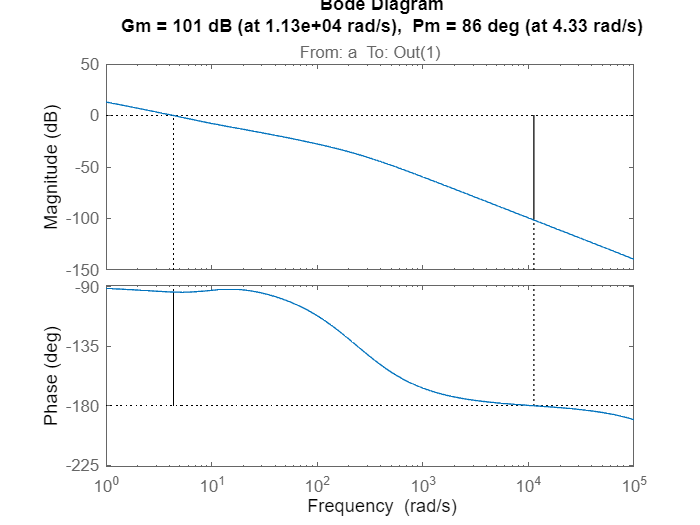

figure
margin(CompensatorCT*Wopen)

### 8 Сравнение компенсаторов

Сравним работу электромеханической системой со всеми 4 компенсаторами между собой при ступенчатом входном сигнале и единичном возмущении.

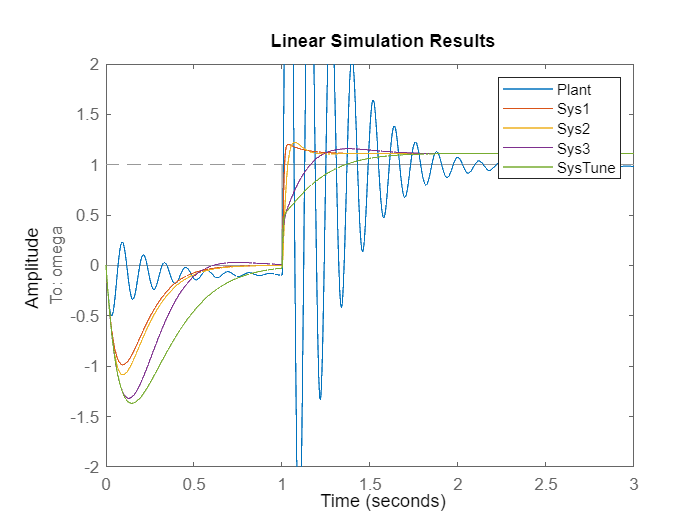

tend = 10; % время симуляции
st = 0.001; % шаг интегрирования
t = (0:st:tend)';
u = @step_u; % входной сигнал
u_sim = zeros(size(t));
for i = 1:length(t)
    u_sim(i) = u(t(i));
end
Msim = ones(size(t)); % возмущение
figure
lsim(Plant,Sys1,Sys2,Sys3,SysTune,[u_sim Msim],t) % симуляция моделей
legend
xlim([0 3])
ylim([-2 2])

Заметим, что последний 4 компенсатор оказался самым "плавным", а самым "быстрым" - первый. Видно, насколько лучше стала работа с компенсатором в сравнении с исходной системой. 

В статье были продемонстрированы далеко не все возможности Matlab по расчету регуляторов. Но данные примеры могут существенно облегчить жизнь как студентам по специальностям, связанным с ТАУ, так и обычным инженерам.

function y = step_u(x)
        if x<=1
            y = 0;
        else
            y = 1;
        end
end